## Comparison of all the Fday FreaqD Data

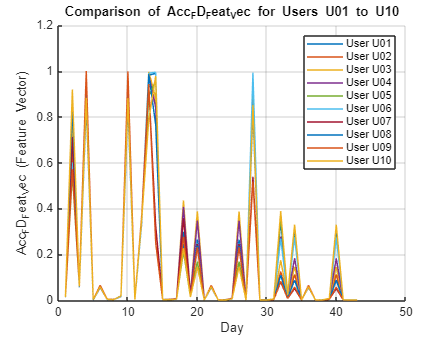

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

accFD_Feat_Vec = [];

for userIdx = 1:10
    userFile = sprintf('U%02d_Acc_FreqD_FDay.mat', userIdx);
    
    data = load(fullfile(dataFolder, userFile));
    
    if isfield(data, 'Acc_FD_Feat_Vec')
        accFD_Feat_Vec(userIdx, :) = data.Acc_FD_Feat_Vec(1, :); % Assuming you want the first row
    else
        disp(['Variable Acc_FD_Feat_Vec not found in ' userFile]);
    end
end

if ~isempty(accFD_Feat_Vec)
    figure;
    hold on;
    for userIdx = 1:10
        plot(accFD_Feat_Vec(userIdx, :), 'DisplayName', sprintf('User U%02d', userIdx));
    end
    hold off;

    xlabel('Day');
    ylabel('Acc_FD_Feat_Vec (Feature Vector)');
    title('Comparison of Acc_FD_Feat_Vec for Users U01 to U10');
    legend;
    grid on;
else
    disp('No valid data to plot.');
end

## Comparison of all the Mday FreaqD Data

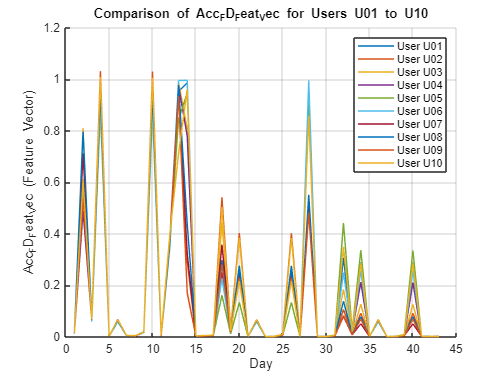

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

accFD_Feat_Vec = [];

for userIdx = 1:10
    userFile = sprintf('U%02d_Acc_FreqD_MDay.mat', userIdx);
    
    data = load(fullfile(dataFolder, userFile));
    
    if isfield(data, 'Acc_FD_Feat_Vec')
        accFD_Feat_Vec(userIdx, :) = data.Acc_FD_Feat_Vec(1, :); % Assuming you want the first row
    else
        disp(['Variable Acc_FD_Feat_Vec not found in ' userFile]);
    end
end

if ~isempty(accFD_Feat_Vec)
    figure;
    hold on;
    for userIdx = 1:10
        plot(accFD_Feat_Vec(userIdx, :), 'DisplayName', sprintf('User U%02d', userIdx));
    end
    hold off;

    xlabel('Day');
    ylabel('Acc_FD_Feat_Vec (Feature Vector)');
    title('Comparison of Acc_FD_Feat_Vec for Users U01 to U10');
    legend;
    grid on;
else
    disp('No valid data to plot.');
end

## Comparison of all the Fday TimeD Data

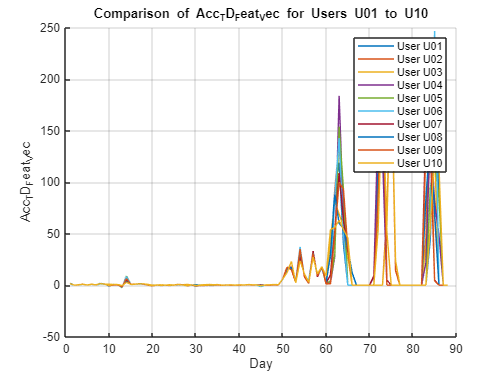

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

accTD_Feat_Vec = [];

for userIdx = 1:10
    userFile = sprintf('U%02d_Acc_TimeD_FDay.mat', userIdx);

    data = load(fullfile(dataFolder, userFile));

    if isfield(data, 'Acc_TD_Feat_Vec')
        
        accTD_Feat_Vec(userIdx, :) = data.Acc_TD_Feat_Vec(1, :); 
    else
        disp(['Variable Acc_TD_Feat_Vec not found in ' userFile]);
    end
end

if ~isempty(accTD_Feat_Vec)
    figure;
    hold on;
    for userIdx = 1:10
        plot(accTD_Feat_Vec(userIdx, :), 'DisplayName', sprintf('User U%02d', userIdx));
    end
    hold off;

    xlabel('Day');
    ylabel('Acc_TD_Feat_Vec');
    title('Comparison of Acc_TD_Feat_Vec for Users U01 to U10');
    legend;
    grid on;
else
    disp('No valid data to plot.');
end

## Comparison of all the Mday TimeD Data

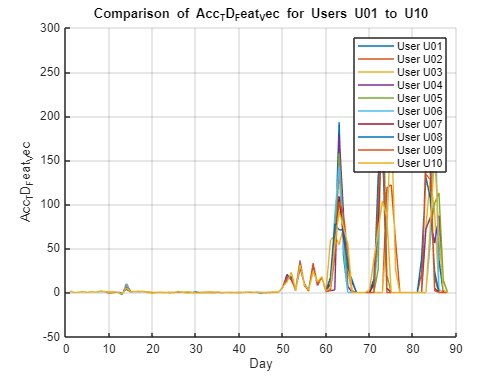

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

accTD_Feat_Vec = [];

for userIdx = 1:10
    userFile = sprintf('U%02d_Acc_TimeD_MDay.mat', userIdx);

    data = load(fullfile(dataFolder, userFile));

    if isfield(data, 'Acc_TD_Feat_Vec')
        
        accTD_Feat_Vec(userIdx, :) = data.Acc_TD_Feat_Vec(1, :); 
    else
        disp(['Variable Acc_TD_Feat_Vec not found in ' userFile]);
    end
end

if ~isempty(accTD_Feat_Vec)
    figure;
    hold on;
    for userIdx = 1:10
        plot(accTD_Feat_Vec(userIdx, :), 'DisplayName', sprintf('User U%02d', userIdx));
    end
    hold off;

    xlabel('Day');
    ylabel('Acc_TD_Feat_Vec');
    title('Comparison of Acc_TD_Feat_Vec for Users U01 to U10');
    legend;
    grid on;
else
    disp('No valid data to plot.');
end

## Comapre of all the Fday TimeD_FreqD Data

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

accTDFD_Feat_Vec_FDay_allUsers = cell(1, 10);

for userIdx = 1:10
    userFile = sprintf('U%02d_Acc_TimeD_FreqD_FDay.mat', userIdx);

    data_FDay = load(fullfile(dataFolder, userFile));

    if isfield(data_FDay, 'Acc_TDFD_Feat_Vec')
        accTDFD_Feat_Vec_FDay_allUsers{userIdx} = data_FDay.Acc_TDFD_Feat_Vec;
    else
        disp(['Variable Acc_TDFD_Feat_Vec not found in ' userFile]);
    end
end

for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        Acc_TDFD_Feat_Vec_FDay = accTDFD_Feat_Vec_FDay_allUsers{userIdx};
        
        disp(['Statistics for User U', num2str(userIdx), ' FDay dataset:']);
        disp(['Mean: ', num2str(mean(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(['Standard Deviation: ', num2str(std(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(['Max: ', num2str(max(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(['Min: ', num2str(min(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(' ');
    end
end

Statistics for User U1 FDay dataset:


Mean: 8.0151


Standard Deviation: 30.83


Max: 255


Min: -1.5813


Statistics for User U2 FDay dataset:


Mean: 8.0768


Standard Deviation: 27.642


Max: 217


Min: -1.9261


Statistics for User U3 FDay dataset:


Mean: 8.0795


Standard Deviation: 27.8201


Max: 261


Min: -0.71761


Statistics for User U4 FDay dataset:


Mean: 8.0255


Standard Deviation: 30.2821


Max: 241


Min: -2.3235


Statistics for User U5 FDay dataset:


Mean: 8.0446


Standard Deviation: 33.3348


Max: 300


Min: -2.429


Statistics for User U6 FDay dataset:


Mean: 8.0251


Standard Deviation: 33.3223


Max: 292


Min: -2.2418


Statistics for User U7 FDay dataset:


Mean: 8.0027


Standard Deviation: 28.3591


Max: 224


Min: -1.0425


Statistics for User U8 FDay dataset:


Mean: 8.0039


Standard Deviation: 27.9983


Max: 253


Min: -0.85241


Statistics for User U9 FDay dataset:


Mean: 8.0059


Standard Deviation: 28.9026


Max: 225


Min: -1.6674


Statistics for User U10 FDay dataset:


Mean: 7.9926


Standard Deviation: 25.2975


Max: 196


Min: -1.8331


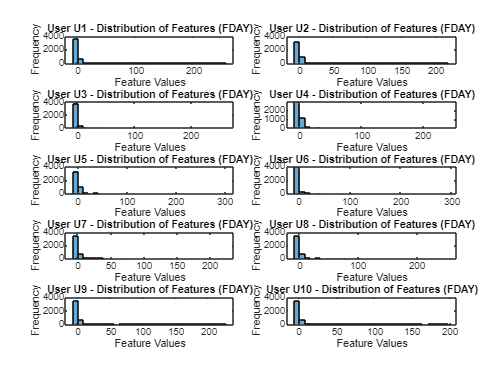

figure;
for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        subplot(5, 2, userIdx);
        histogram(accTDFD_Feat_Vec_FDay_allUsers{userIdx}(:), 30);
        title(['User U', num2str(userIdx), ' - Distribution of Features (FDAY)']);
        xlabel('Feature Values');
        ylabel('Frequency');
    end
end

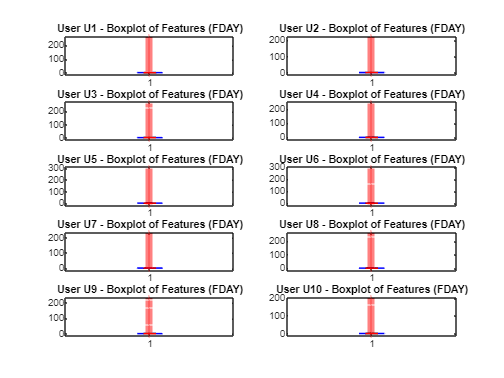

figure;
for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        subplot(5, 2, userIdx);
        boxplot(accTDFD_Feat_Vec_FDay_allUsers{userIdx}(:), 'Notch', 'on');
        title(['User U', num2str(userIdx), ' - Boxplot of Features (FDAY)']);
    end
end

allUsers_FDay_data = [];
for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        allUsers_FDay_data = [allUsers_FDay_data, accTDFD_Feat_Vec_FDay_allUsers{userIdx}(:)];
    end
end

correlation_matrix_FDay = corr(allUsers_FDay_data);
disp('Correlation Matrix between Users FDay Features:');

Correlation Matrix between Users FDay Features:


disp(correlation_matrix_FDay);

    1.0000    0.4000    0.4056    0.7506    0.9252    0.9351    0.6906    0.6744    0.6648    0.8186
    0.4000    1.0000    0.8350    0.5377    0.4130    0.4026    0.5201    0.4801    0.5069    0.3911
    0.4056    0.8350    1.0000    0.4101    0.3664    0.4450    0.3417    0.3146    0.3423    0.4945
    0.7506    0.5377    0.4101    1.0000    0.7402    0.6994    0.7879    0.7175    0.7779    0.5988
    0.9252    0.4130    0.3664    0.7402    1.0000    0.8732    0.7605    0.7220    0.7349    0.7419
    0.9351    0.4026    0.4450    0.6994    0.8732    1.0000    0.6604    0.6611    0.6292    0.7622
    0.6906    0.5201    0.3417    0.7879    0.7605    0.6604    1.0000    0.9519    0.9657    0.5478
    0.6744    0.4801    0.3146    0.7175    0.7220    0.6611    0.9519    1.0000    0.9282    0.5596
    0.6648    0.5069    0.3423    0.7779    0.7349    0.6292    0.9657    0.9282    1.0000    0.5498
    0.8186    0.3911    0.4945    0.5988    0.7419    0.7622    0.5478    0.5596    0.5498 

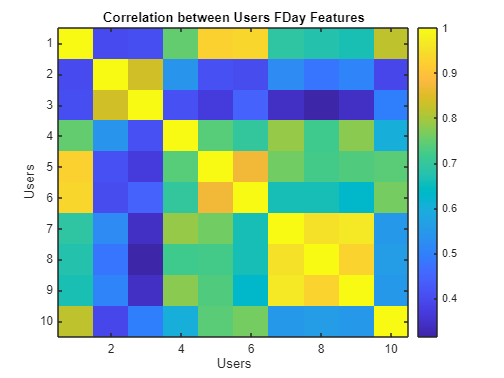

figure;
imagesc(correlation_matrix_FDay);
colorbar;
title('Correlation between Users FDay Features');
xlabel('Users');
ylabel('Users');

## Comapre of all the Mday TimeD_FreqD Data

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

accTDFD_Feat_Vec_FDay_allUsers = cell(1, 10);

for userIdx = 1:10
    userFile = sprintf('U%02d_Acc_TimeD_FreqD_MDay.mat', userIdx);

    data_FDay = load(fullfile(dataFolder, userFile));

    if isfield(data_FDay, 'Acc_TDFD_Feat_Vec')
        accTDFD_Feat_Vec_FDay_allUsers{userIdx} = data_FDay.Acc_TDFD_Feat_Vec;
    else
        disp(['Variable Acc_TDFD_Feat_Vec not found in ' userFile]);
    end
end

for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        Acc_TDFD_Feat_Vec_FDay = accTDFD_Feat_Vec_FDay_allUsers{userIdx};
        
        disp(['Statistics for User U', num2str(userIdx), ' FDay dataset:']);
        disp(['Mean: ', num2str(mean(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(['Standard Deviation: ', num2str(std(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(['Max: ', num2str(max(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(['Min: ', num2str(min(Acc_TDFD_Feat_Vec_FDay(:)))]);
        disp(' ');
    end
end

Statistics for User U1 FDay dataset:


Mean: 8.0062


Standard Deviation: 30.6863


Max: 256


Min: -2.5653


Statistics for User U2 FDay dataset:


Mean: 8.0697


Standard Deviation: 27.2632


Max: 184


Min: -1.625


Statistics for User U3 FDay dataset:


Mean: 8.0799


Standard Deviation: 26.9398


Max: 236


Min: -0.66654


Statistics for User U4 FDay dataset:


Mean: 8.0207


Standard Deviation: 29.2511


Max: 235


Min: -2.5958


Statistics for User U5 FDay dataset:


Mean: 8.0307


Standard Deviation: 31.0409


Max: 281


Min: -2.5159


Statistics for User U6 FDay dataset:


Mean: 8.0274


Standard Deviation: 32.8646


Max: 280


Min: -2.2166


Statistics for User U7 FDay dataset:


Mean: 8.0027


Standard Deviation: 28.3591


Max: 224


Min: -1.0425


Statistics for User U8 FDay dataset:


Mean: 7.9903


Standard Deviation: 28.2172


Max: 219


Min: -0.82686


Statistics for User U9 FDay dataset:


Mean: 8.02


Standard Deviation: 27.7126


Max: 241


Min: -1.6098


Statistics for User U10 FDay dataset:


Mean: 8.0187


Standard Deviation: 25.337


Max: 203


Min: -1.9481


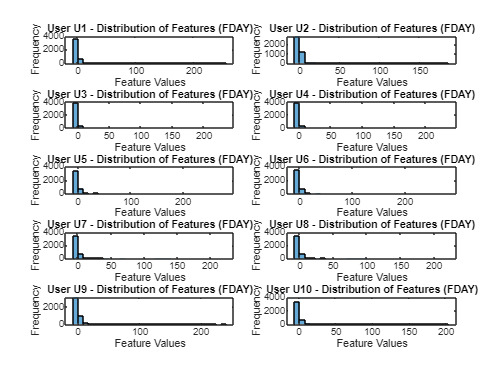


figure;
for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        subplot(5, 2, userIdx);
        histogram(accTDFD_Feat_Vec_FDay_allUsers{userIdx}(:), 30);
        title(['User U', num2str(userIdx), ' - Distribution of Features (FDAY)']);
        xlabel('Feature Values');
        ylabel('Frequency');
    end
end

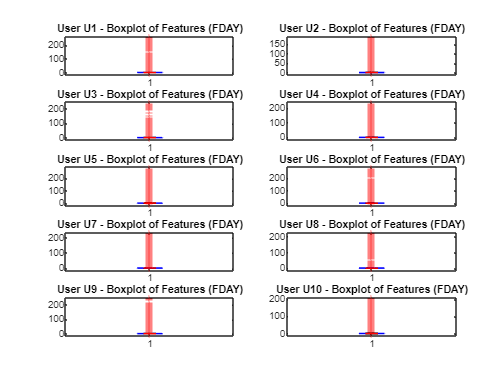


figure;
for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        subplot(5, 2, userIdx);
        boxplot(accTDFD_Feat_Vec_FDay_allUsers{userIdx}(:), 'Notch', 'on');
        title(['User U', num2str(userIdx), ' - Boxplot of Features (FDAY)']);
    end
end


allUsers_FDay_data = [];
for userIdx = 1:10
    if ~isempty(accTDFD_Feat_Vec_FDay_allUsers{userIdx})
        allUsers_FDay_data = [allUsers_FDay_data, accTDFD_Feat_Vec_FDay_allUsers{userIdx}(:)];
    end
end

correlation_matrix_FDay = corr(allUsers_FDay_data);
disp('Correlation Matrix between Users FDay Features:');

Correlation Matrix between Users FDay Features:


disp(correlation_matrix_FDay);

    1.0000    0.2743    0.3778    0.7831    0.9045    0.9609    0.7003    0.6399    0.7003    0.6453
    0.2743    1.0000    0.7910    0.5300    0.3899    0.2490    0.5787    0.5480    0.5625    0.3429
    0.3778    0.7910    1.0000    0.4234    0.3762    0.3737    0.4060    0.3808    0.4101    0.4819
    0.7831    0.5300    0.4234    1.0000    0.8490    0.7345    0.8487    0.7718    0.8391    0.5620
    0.9045    0.3899    0.3762    0.8490    1.0000    0.8745    0.7612    0.6846    0.7635    0.6312
    0.9609    0.2490    0.3737    0.7345    0.8745    1.0000    0.6763    0.6192    0.6763    0.6409
    0.7003    0.5787    0.4060    0.8487    0.7612    0.6763    1.0000    0.9691    0.9659    0.4442
    0.6399    0.5480    0.3808    0.7718    0.6846    0.6192    0.9691    1.0000    0.9550    0.4056
    0.7003    0.5625    0.4101    0.8391    0.7635    0.6763    0.9659    0.9550    1.0000    0.5216
    0.6453    0.3429    0.4819    0.5620    0.6312    0.6409    0.4442    0.4056    0.5216 

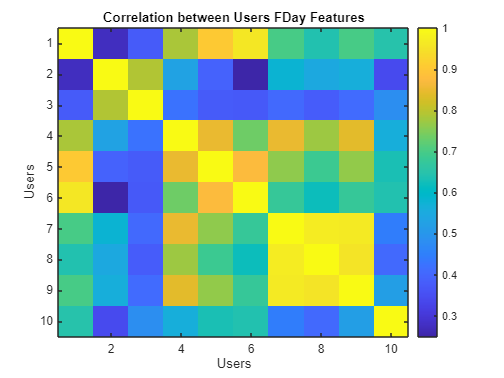


figure;
imagesc(correlation_matrix_FDay);
colorbar;
title('Correlation between Users FDay Features');
xlabel('Users');
ylabel('Users');